% 1. Read the Image into MATLAB.
img = imread('AS1-3/Galaxy.png');
img = rgb2gray(img)

img = 644x699 uint8 matrix
   17   22   18   23   21   23   17   18   18   18   18   18   21   22   21   18   23   24   24   18   14   17   21   22   26   18   22   17   24   17   18   20   15   18   18   22   19   18   17   18   17   14   18   21   14   16   18   18   20   23
   18   17   17   21   18   22   18   18   20   22   18   18   17   22   18   22   23   20   25   21   18   14   20   18   22   24   19   25   23   18   22   17   19   18   17   14   14   15   19   23   20   18   18   18   19   18   18   17   22   22
   16   18   22   18   22   12   20   19   20   18   18   18   17   18   18   18   25   19   20   18   17   18   22   23   25   25   27   25   25   23   23   22   17   19   18   16   18   21   17   17   18   24   26   17   17   17   17   25   14   18
   14   25   22   18   18   19   18   18   18   22   23   18   17   23   17   18   22   17   22   18   22   21   19   19   20   26   28   35   35   22   23   20   16   18   18   18   17   18   18   16   16   18   18   18


% 1. Extract and save all 8 bit planes individually.
for k = 1:8
    bit_plane = bitget(img, k);
    imwrite(bit_plane, sprintf('BitPlane%d.png', k));
end

% 2. Use the three most significant bit planes (5th, 6th, and 7th) to reconstruct the image.
reconstructed_img = 2^4 * imread('BitPlane5.png') + 2^5 * imread('BitPlane6.png') + 2^6 * imread('BitPlane7.png');
imwrite(reconstructed_img, 'Reconstructed.png');

% 3. Enhance edges with the Sobel operator.
% ref: https://www.mathworks.com/help/images/ref/edge.html
edges = edge(reconstructed_img, 'sobel');
imwrite(edges, 'Edges.png');

% 4. Reduce noise with a median filter.
filtered_img = medfilt2(edges);
imwrite(filtered_img, 'Filtered.png');

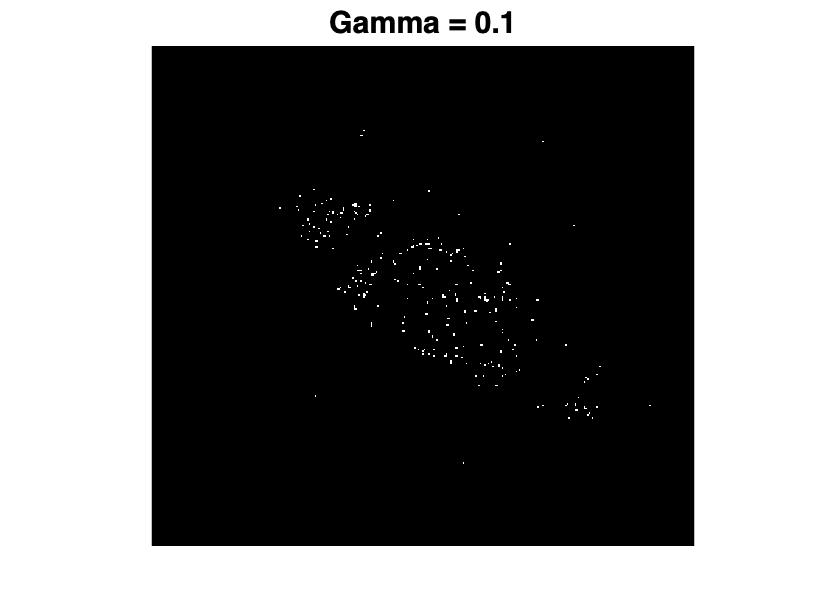

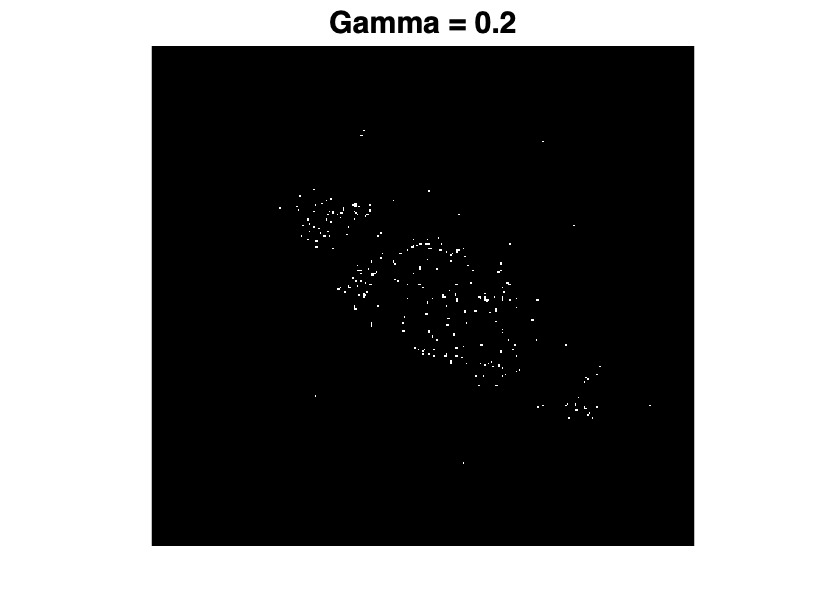

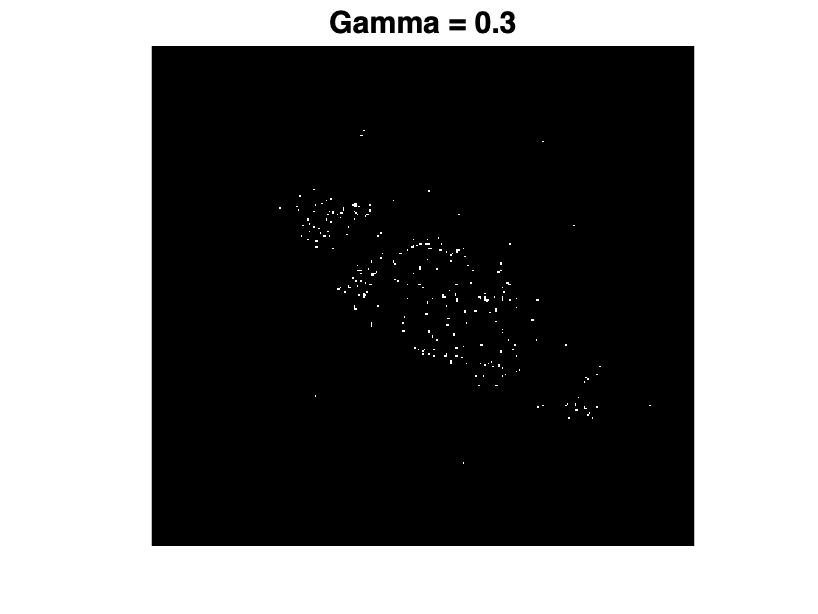

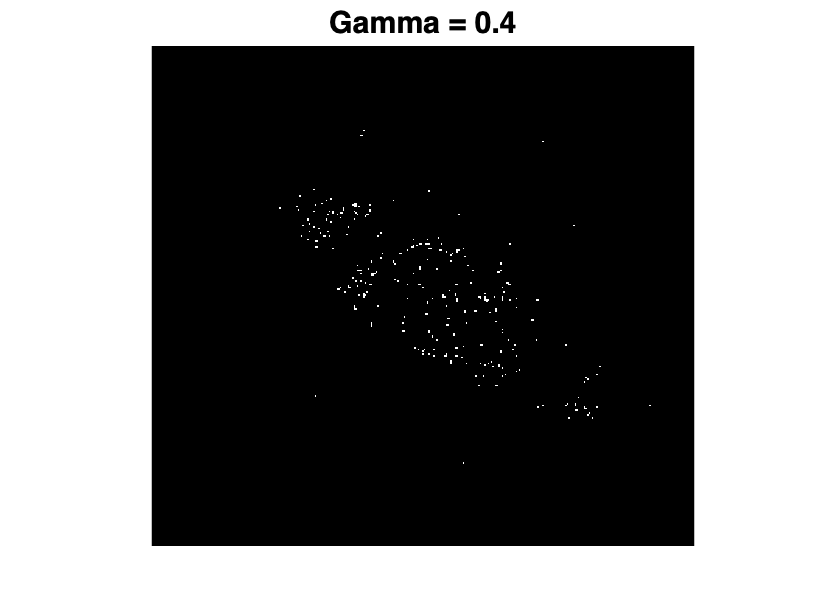

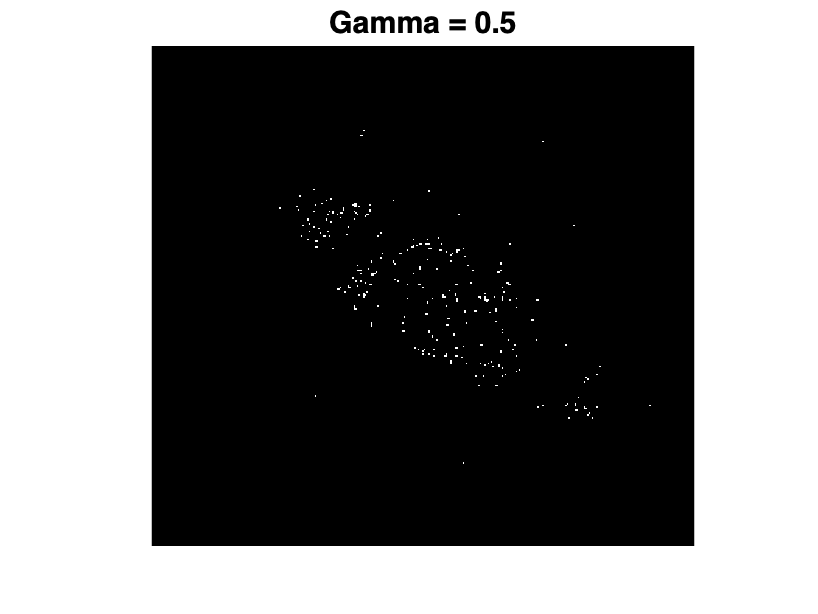

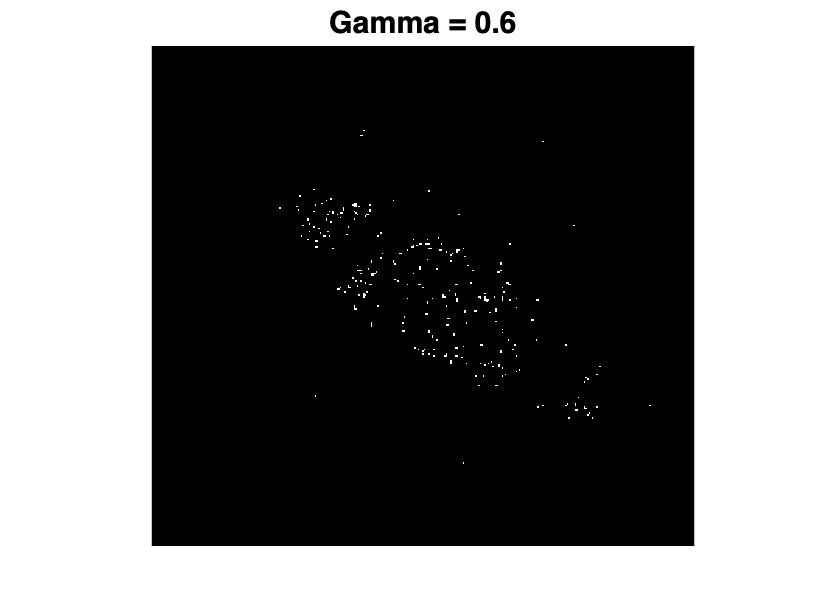

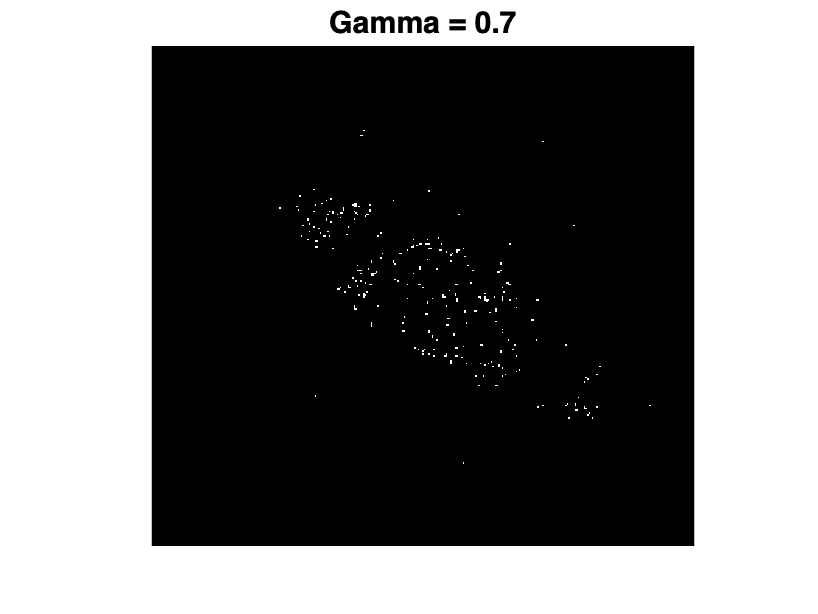

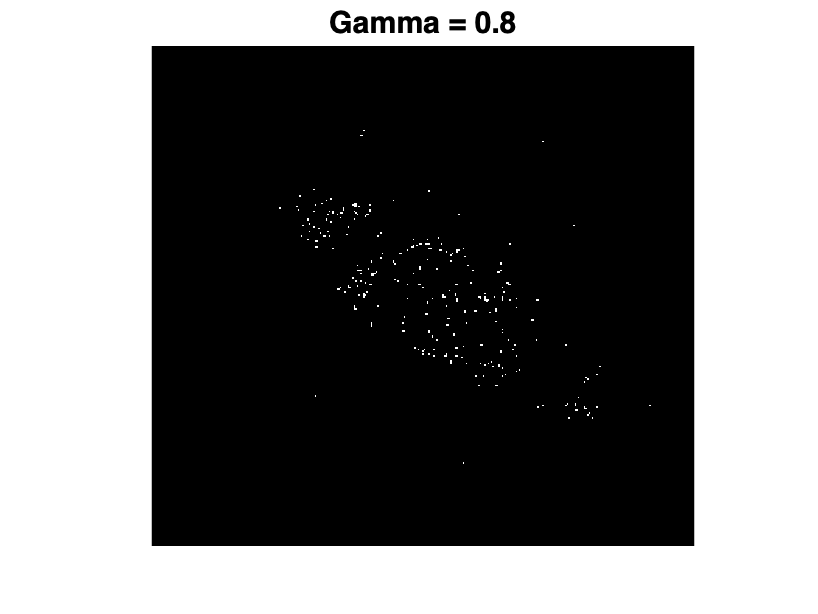

% 5. Apply gamma correction using a gamma value
% Convert the logical image to uint8 before applying imadjust so that there
% is no error for it that type was logical 
filtered_img_uint8 = uint8(filtered_img * 255);
% Try gamma values from 0.1 to 2.0 in steps of 0.1
for gamma = 0.1:0.1:2.0
    gamma_corrected_img = imadjust(filtered_img_uint8, [], [], gamma);
    figure, imshow(gamma_corrected_img), title(['Gamma = ', num2str(gamma)]);
end

% after trying to print it out, I dont see that much change? So I will just
% use gamma = 1 for this 
gamma_corrected_img = imadjust(filtered_img_uint8, [], [], 1.0);
imwrite(gamma_corrected_img, 'GammaCorrected.png');